# Project: Beam and Ball

## Problem Statement

As shown in the figure below, a ball is placed on a beam, where it rolls under the influence of gravity. The ball has one degree of freedom along the length of the beam. The beam's angle is adjusted using a lever arm connected to the beam at one end and to a servo motor gear at the other. As the servo gear rotates by an angle θ about its axis, the lever arm angle changes by ɑ from the horizontal.

### Assumptions: 

The ball remains in contact with the beam at all times. The ball performs pure rolling motion (rolling without slipping)

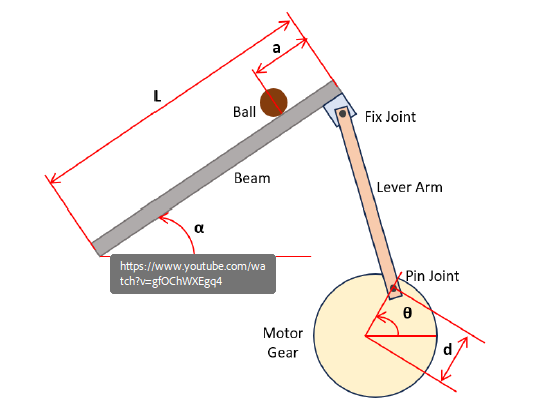

## System's Transfer function

m = 0.5;
r = 0.05;
d = 0.1;
L = 1.0;
I = (2 * m * (r^2))/5;
x = 0.5;
alpha = 0.1;
theta = 0.1;
k = 0.12;
g = 9.81;

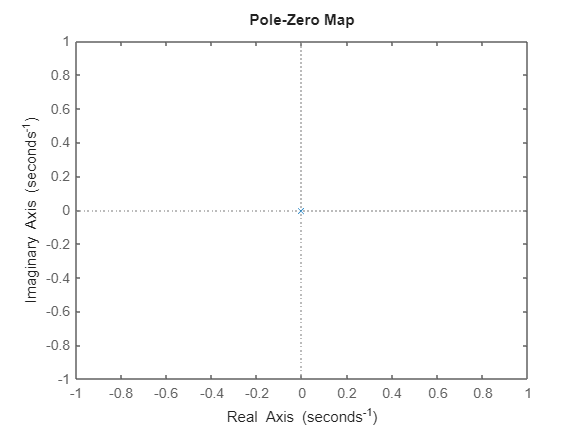

num = [0 0 -m*g*k];
den = [m + I/r^2 0 0];
TF = tf(num, den);
pzmap(TF)

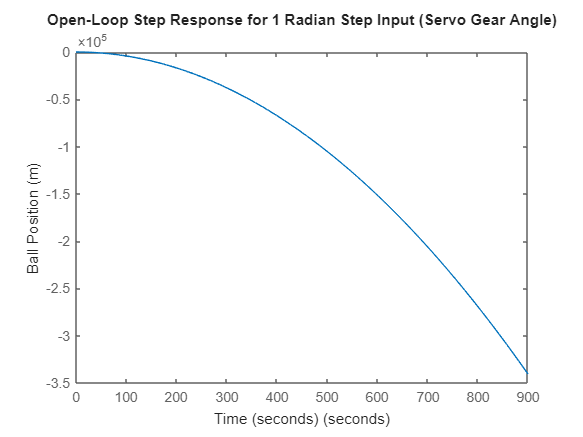

step(TF)
title('Open-Loop Step Response for 1 Radian Step Input (Servo Gear Angle)')
xlabel('Time (seconds)')
ylabel('Ball Position (m)')